%load and format tracks 
cd C:\Users\Hailey\CPSAM_OriginalUTURN
filename='CPSAM_Original_Tracks.xml'; %'pos1croptest_Tracks.xml';%; %'pos1croptest_Tracks.xml' %'Pos1_Tracks.xml'; %7.23.25 pos 1 dataset
labelstif='C:\Users\Hailey\CPSAM_OriginalUTURN\LabelImageSeq\LblImgALL.tif'; %'LblImg_pos1croptestlabels.tif' %'LblImg_pos1_labels.tif';
directory='C:\Users\Hailey\CPSAM_OriginalUTURN\LabelImageSeq\';

[tracks, disps]=TracksForm(filename,labelstif,mindur=50,stimstart=1);
 
%re-modify tracks
msdtracks=tracks;
for i=1:length(tracks)
    msdtracks{i}=tracks{i}(:,1:3);
end
% Initialize the MSD analyzer with the specified parameters
ma = msdanalyzer(2, 'px', 'frame');
ma = ma.addAll(msdtracks);

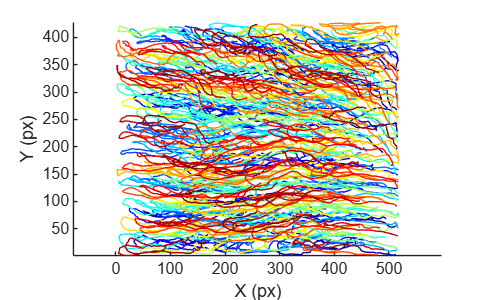

figure
ma.plotTracks;
ma.labelPlotTracks;

ma = ma.computeMSD;

Computing MSD of 391 tracks...   Done.


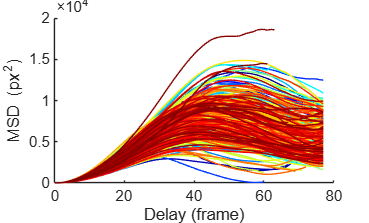

figure
ma.plotMSD;

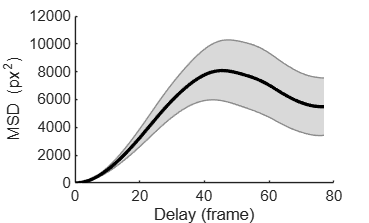

figure
ma.plotMeanMSD(gca, true)

figure
v = ma.getVelocities;
ma = ma.computeVCorr;

Computing velocity autocorrelation of 391 tracks... Done.


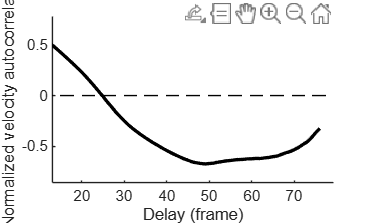

ma.plotMeanVCorr

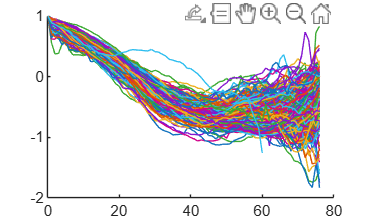

figure
hold on
for i=1:length(ma.vcorr)
    plot(ma.vcorr{i,1}(:,1),ma.vcorr{i,1}(:,2)) 
end

%break tracks before, after turn;
%for before, Ive seen order is acheived at ~frame 6, so I might want to
%compare 0-30 and 6-30


%BEFORE (1-30)

%re-modify tracks
beforetracks=tracks;
for i=1:length(tracks)
    row6=length(find(tracks{i}(:,1)<6));
    if row6==0
        row6=1;
    end
    row30=length(find(tracks{i}(:,1)<30));
    msdtracks{i}=tracks{i}(row6:row30,1:3);
end
% Initialize the MSD analyzer with the specified parameters
ma = msdanalyzer(2, 'px', 'frame');
ma = ma.addAll(msdtracks);
figure
ma.plotTracks;
ma.labelPlotTracks;
ma = ma.computeMSD;

Computing MSD of 391 tracks...   Done.


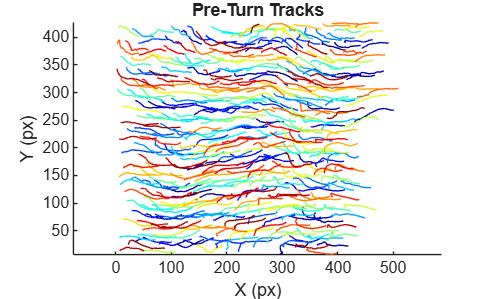

title('Pre-Turn Tracks')

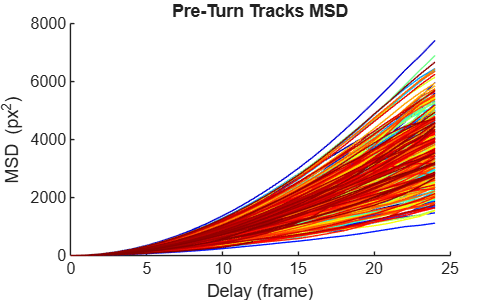

figure
ma.plotMSD;
title('Pre-Turn Tracks MSD')

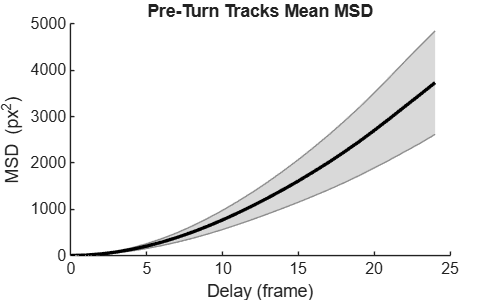

figure
ma.plotMeanMSD(gca, true)
title('Pre-Turn Tracks Mean MSD')

figure
v = ma.getVelocities;
ma = ma.computeVCorr;

Computing velocity autocorrelation of 391 tracks... Done.


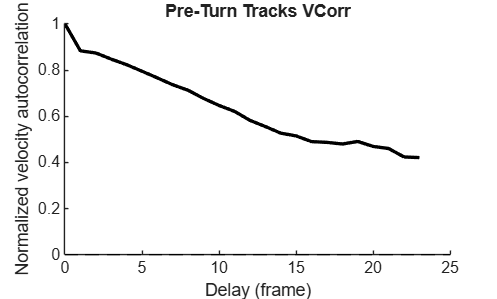

ma.plotMeanVCorr
title('Pre-Turn Tracks VCorr')

%AFTER (35-79)

%re-modify tracks
beforetracks=tracks;
for i=1:length(tracks)
    row35=length(find(tracks{i}(:,1)<35));
    msdtracks{i}=tracks{i}(row35:end,1:3);
end
% Initialize the MSD analyzer with the specified parameters
ma = msdanalyzer(2, 'px', 'frame');
ma = ma.addAll(msdtracks);
figure
ma.plotTracks;
ma.labelPlotTracks;
ma = ma.computeMSD;

Computing MSD of 391 tracks...   Done.


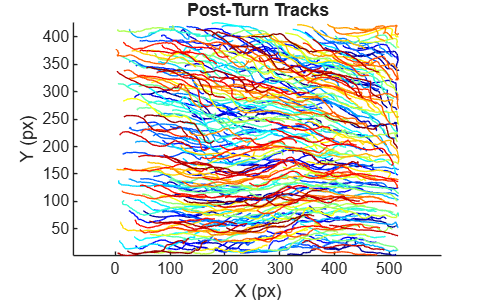

title('Post-Turn Tracks')

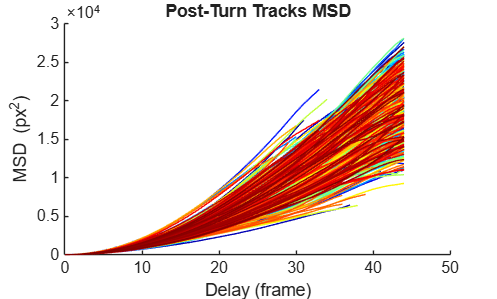

figure
ma.plotMSD;
title('Post-Turn Tracks MSD')

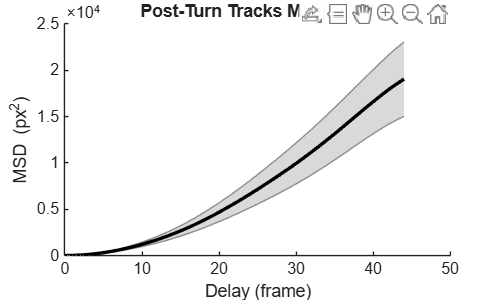

figure
ma.plotMeanMSD(gca, true)
title('Post-Turn Tracks Mean MSD')

figure
v = ma.getVelocities;
ma = ma.computeVCorr;

Computing velocity autocorrelation of 391 tracks... Done.


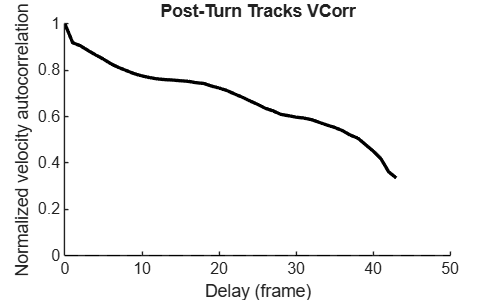

ma.plotMeanVCorr
title('Post-Turn Tracks VCorr')